# 1: 適当にIMCL0%のサンプルのRFデータを呼び出す．

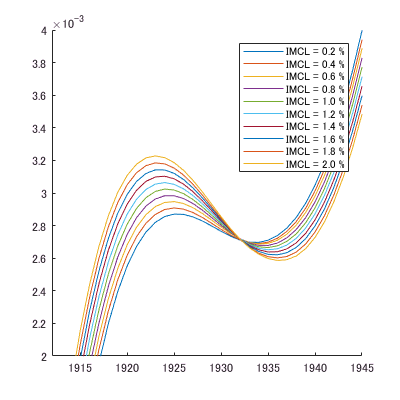

legendInfo = cell(1,10);
figure;hold on
for ii = 2:2:20
    loadfilename = sprintf("H:/data/kwave/result/2018_10_15_realisticScatter_variousIMCL_Correct/case1_IMCL%0.1f/rfdata.mat",ii/10);
    load(loadfilename);
    plot(rfdata(:,150,50));
    legendInfo{ii/2} = sprintf('IMCL = %0.1f %%',ii/10);
end
legend(legendInfo);
exportfig("H:/result/2018_10_16_analyzeRFdata_IMCLchg/RFdata_IMCLchg",'png',[400,400]);
xlim([1764 2635])
ylim([-0.045 0.069])
exportfig("H:/result/2018_10_16_analyzeRFdata_IMCLchg/RFdata_IMCLchg1",'png',[400,400]);
xlim([2163 2257])
ylim([0.001 0.024])
exportfig("H:/result/2018_10_16_analyzeRFdata_IMCLchg/RFdata_IMCLchg2",'png',[400,400]);
xlim([2181 2199])
ylim([0.018 0.022])
exportfig("H:/result/2018_10_16_analyzeRFdata_IMCLchg/RFdata_IMCLchg3",'png',[400,400]);
xlim([1912 1945])
ylim([0.002 0.004])
exportfig("H:/result/2018_10_16_analyzeRFdata_IMCLchg/RFdata_IMCLchg4",'png',[400,400]);

## 2

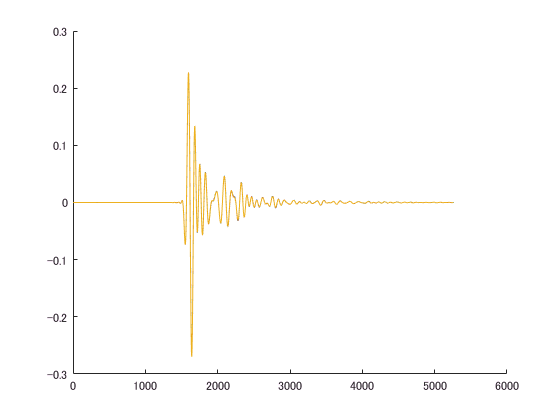

figure;hold on
rfdata_cell = cell(1,20);
for ii = 2:2:20
    loadfilename = sprintf("H:/data/kwave/result/2018_10_15_realisticScatter_variousIMCL_Correct/case1_IMCL%0.1f/rfdata.mat",ii/10);
    load(loadfilename);
    rfdata_cell{ii} = rfdata;
    plot(rfdata(:,150,50));
    legendInfo{ii/2} = sprintf('IMCL = %0.1f %%',ii/10);
end

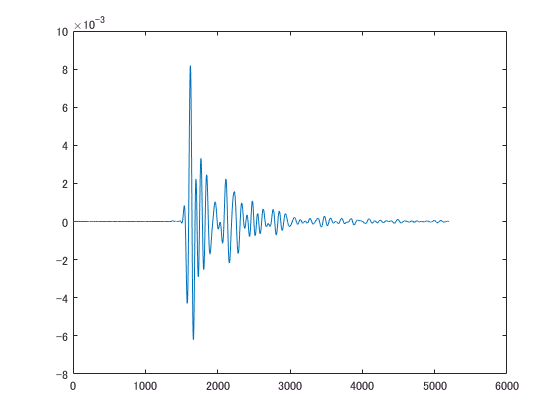

figure;
plot(rfdata_cell{2}(1:5200,150,50) - rfdata_cell{20}(1:5200,150,50));

## 3

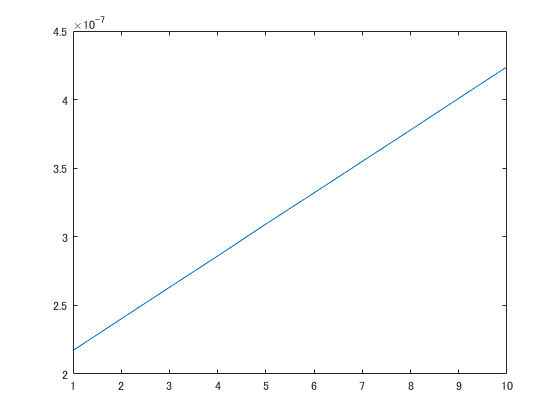

amplitude_cell = zeros(1,10);
for ii = 1:10
    amplitude_cell(ii) = sum(abs(rfdata_cell{ii*2}(1:5,150,50)));
end
figure;
plot(amplitude_cell);

単調増加した．透過率との兼ね合いだろうが，ほとんど検出できるようなレベルのものではない．

## 4

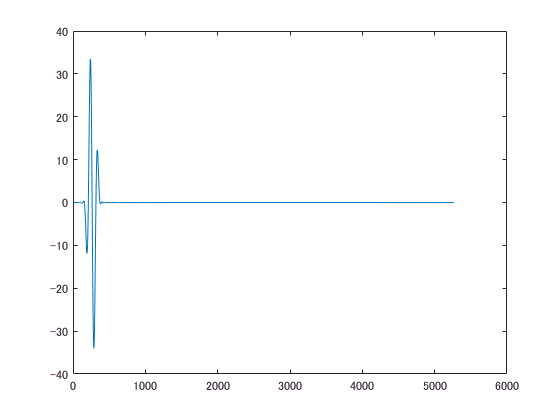

load("H:/data/kwave/result/2018_10_15_realisticScatter_variousIMCL_Correct/case1_IMCL0.2/sourse_wave.mat")
figure;
plot(source_wave);

## 5

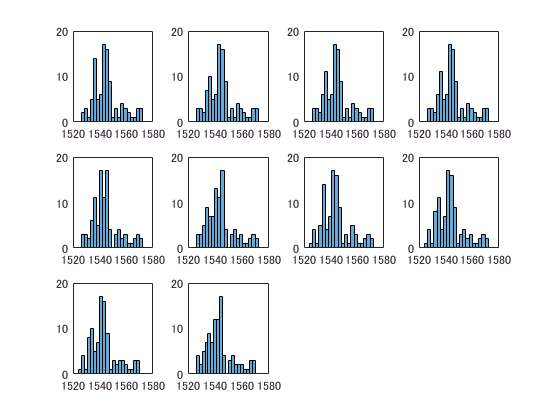

load("H:/data/kwave/result/2018_10_15_realisticScatter_variousIMCL_Correct/EMCL_num_75/statistics.mat")
[~,leng_IMCL,~] = size(SOS2);
figure;
for ii = 1:leng_IMCL
    subplot(3,4,ii);
    histogram(SOS2(:,ii,1),20);
    xlim([1520 1580])
end

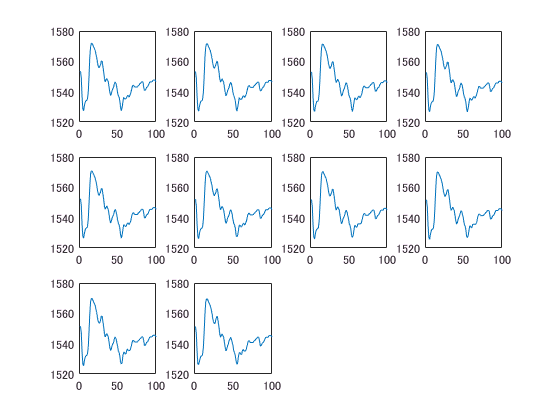

figure;
for ii = 1:leng_IMCL
    subplot(3,4,ii);
    plot(SOS2(:,ii,1));
end

## 6

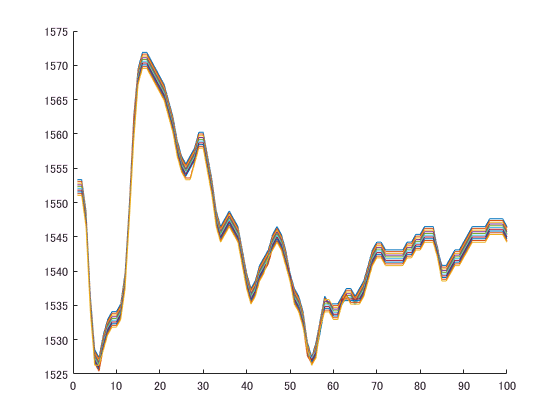

figure;
hold on
for ii = 1:leng_IMCL
    plot(SOS2(:,ii,1));
end

パット見これでは違いがわからない．

全経路を用いた経路平均音速でヒストグラムを作成してみる．

## 7

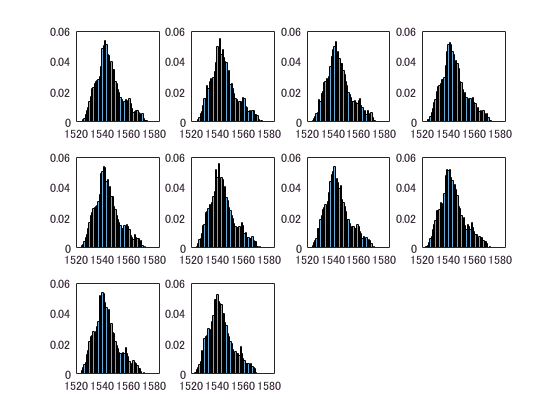

load("H:/data/kwave/result/2018_10_15_realisticScatter_variousIMCL_Correct/EMCL_num_75/statistics.mat")
[~,leng_IMCL,~] = size(SOS2);
figure;
for ii = 1:leng_IMCL
    subplot(3,4,ii);
    histogram(SOS_all(:,:,ii,1),'BinMethod','fd','Normalization','probability');
    xlim([1520 1585])
    ylim([0 0.06])
end

v_muscle = 1580;%筋肉の音速[m/s]
v_fat = 1450;%脂肪の音速[m/s]
reference_max_SOS = zeros(1,10);
for i = 1:10
    reference_max_SOS(1,i) = v_muscle*((100-2*i/10)/100) + v_fat*((2*i/10)/100);
end

## 8

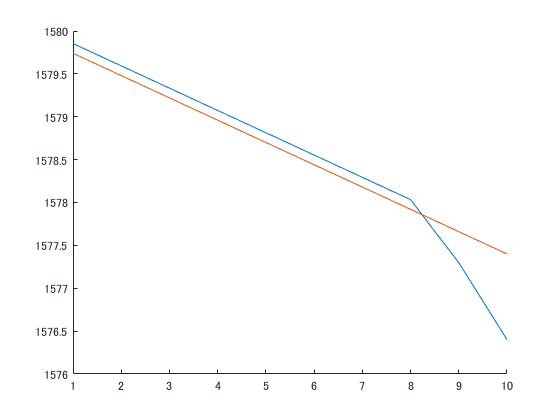

figure;
hold on
plot(max_SOS_all(:,1));
plot(reference_max_SOS(1,:))
hold off

参照用プロットを行う．

全経路中の最大音速を求めれば，IMCL割合が推定できるかもしれない．

75サンプル全てでプロットしてみる．

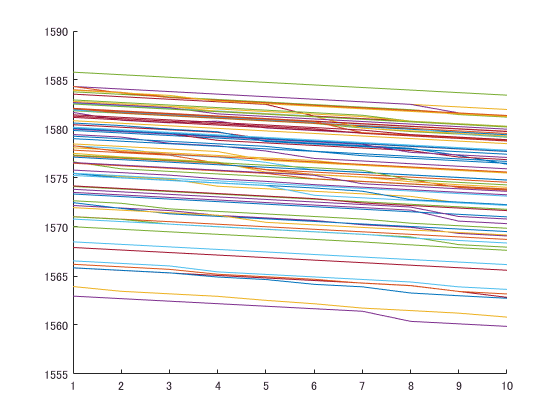

figure;
hold on
for ii = 1:75
    plot(max_SOS_all(:,ii));
end
hold off

1580 m/sを超えている経路が存在している．

## 9: 最大音速をとる経路をプロットしてみる．

load("H:/data/kwave/result/2018_10_15_realisticScatter_variousIMCL_Correct/case1_IMCL0.2/kgrid.mat")
load("H:/data/kwave/config/t_pos_2board.mat")
load("H:/data/kwave/result/2018_10_15_realisticScatter_variousIMCL_Correct/EMCL_num_75/statistics.mat")

load("H:/data/kwave/result/2018_10_15_realisticScatter_variousIMCL_Correct/case1_IMCL0.2/medium.mat")
figure;
imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
axis equal
axis tight
hold on
scatter(t_pos(2,:)*1000,t_pos(1,:)*1000,'rs','filled');
xlabel('y-axis[mm]')
ylabel('x-axis[mm]')
hold on
for i = 1:length(ind_fastest_all)
    plot([t_pos(2,i)*1000;t_pos(2,100+ind_fastest_all(i,1,1))*1000],[t_pos(1,i)*1000;t_pos(1,100+ind_fastest_all(i,1,1))*1000],'.-k','LineWidth',0.01);
end
plot([t_pos(2,ind_fastest(1,1,1))*1000;t_pos(2,100+ind_fastest(2,1,1))*1000],[t_pos(1,ind_fastest(1,1,1))*1000;t_pos(1,100+ind_fastest(2,1,1))*1000],'.-r','LineWidth',1)

## 10: 8の可視化を全サンプルに渡って行う．

load("H:/data/kwave/result/2018_10_15_realisticScatter_variousIMCL_Correct/case1_IMCL0.2/kgrid.mat")
load("H:/data/kwave/config/t_pos_2board.mat")
load("H:/data/kwave/result/2018_10_15_realisticScatter_variousIMCL_Correct/EMCL_num_75/statistics.mat")
[num_IMCL, num_EMCL] = size(rate_EMCLs);
for ii = 1:num_EMCL
    for jj = 1:num_IMCL
        loadfilename = sprintf('H:/data/kwave/result/2018_10_15_realisticScatter_variousIMCL_Correct/case%d_IMCL%0.1f/medium.mat',ii,rate_IMCLs(jj,1)/10);
        load(loadfilename);
        figure;
        imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
        axis equal
        axis tight
        hold on
        scatter(t_pos(2,:)*1000,t_pos(1,:)*1000,'rs','filled');
        xlabel('y-axis[mm]')
        ylabel('x-axis[mm]')
        hold on
        for i = 1:length(ind_fastest_all)
            plot([t_pos(2,i)*1000;t_pos(2,100+ind_fastest_all(i,jj,ii))*1000],[t_pos(1,i)*1000;t_pos(1,100+ind_fastest_all(i,jj,ii))*1000],'.-k','LineWidth',0.01);
        end
        plot([t_pos(2,ind_fastest(1,jj,ii))*1000;t_pos(2,100+ind_fastest(2,jj,ii))*1000],[t_pos(1,ind_fastest(1,jj,ii))*1000;t_pos(1,100+ind_fastest(2,jj,ii))*1000],'.-r','LineWidth',1)
        savefilename = sprintf("H:/result/2018_10_16_analyzeRFdata_IMCLchg/case%d_IMCL%0.1f",ii,rate_IMCLs(jj,1)/10);
        exportfig(savefilename,'png',[300,300]);
    end
end

## 11: 測定した最大音速と理論的な最大音速，そして各素子での最大音速をもつ経路の変動がわかるようなアニメーションを作る．

load("H:/data/kwave/result/2018_10_15_realisticScatter_variousIMCL_Correct/case1_IMCL0.2/kgrid.mat")
load("H:/data/kwave/config/t_pos_2board.mat")
load("H:/data/kwave/result/2018_10_15_realisticScatter_variousIMCL_Correct/EMCL_num_75/statistics.mat")
[num_IMCL, num_EMCL] = size(rate_EMCLs);
v_muscle = 1580;%筋肉の音速[m/s]
v_fat = 1450;%脂肪の音速[m/s]
reference_max_SOS = zeros(1,10);
for i = 1:10
    reference_max_SOS(1,i) = v_muscle*((100-2*i/10)/100) + v_fat*((2*i/10)/100);
end
clear mov;
fr(1:num_EMCL*num_IMCL) = struct('cdata',[],'colormap',[]);

for ii = 1:num_EMCL
    for jj = 1:num_IMCL
        figure(1);
        subplot(2,2,[1,3]);
        loadfilename = sprintf('H:/data/kwave/result/2018_10_15_realisticScatter_variousIMCL_Correct/case%d_IMCL%0.1f/medium.mat',ii,rate_IMCLs(jj,1)/10);
        load(loadfilename);
        imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
        axis equal
        axis tight
        hold on
        scatter(t_pos(2,:)*1000,t_pos(1,:)*1000,'rs','filled');
        xlabel('y-axis[mm]')
        ylabel('x-axis[mm]')
        hold on
        for i = 1:length(ind_fastest_all)
            plot([t_pos(2,i)*1000;t_pos(2,100+ind_fastest_all(i,jj,ii))*1000],[t_pos(1,i)*1000;t_pos(1,100+ind_fastest_all(i,jj,ii))*1000],'.-k','LineWidth',0.001);
        end
        plot([t_pos(2,ind_fastest(1,jj,ii))*1000;t_pos(2,100+ind_fastest(2,jj,ii))*1000],[t_pos(1,ind_fastest(1,jj,ii))*1000;t_pos(1,100+ind_fastest(2,jj,ii))*1000],'.-r','LineWidth',3)
        hold off
        titlename = sprintf('case%d: EMCL=%0.2f %%',ii, rate_EMCLs(1,ii));
        title(titlename);
        subplot(2,2,2);
        plot(rate_EMCLs(1,:));
        hold on
        scatter(ii,rate_EMCLs(1,ii),'filled','r');
        hold off
        xlabel('medium number');
        ylabel('EMCL[%]')
        subplot(2,2,4);
        plot(0.2:0.2:2.0,max_SOS_all(:,ii));
        hold on
        plot(0.2:0.2:2.0,reference_max_SOS(1,:));
        scatter(jj*0.2, max_SOS_all(jj,ii),'filled','red');
        hold off
        xlabel('IMCL[%]');
        ylabel('maximum velocity[m/s]')
        xlim([0 2.2]);
        ylim([1558 1587])
        legend('measure','reference','Location','best');
        pause(0.05);
        drawnow;
        fr(jj+(ii-1)*num_IMCL) = getframe(gcf);
    end
end
% play movie
figure;
movie(fr)
% save movie
cd('H:\result\2018_10_16_analyzeRFdata_IMCLchg')
mv = VideoWriter('maximum_velocity_path_IMCLchg','MPEG-4');
mv.FrameRate = 5; % ← fpsと同じ %ART:3
open(mv)
writeVideo(mv,fr)
close(mv)

% for ii = 1:num_EMCL
%     for jj = 1:num_IMCL
%         disp(jj+(ii-1)*num_IMCL);
%     end
% end